%recording
fs_r = 48000; 
nBits = 24; 
nChannels = 1; 
ID = -1;       % default audio input device 
recObj = audiorecorder(fs_r,nBits,nChannels,ID);
disp("Begin speaking.")

Begin speaking.


recDuration = 10; % record for 5 seconds
recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.


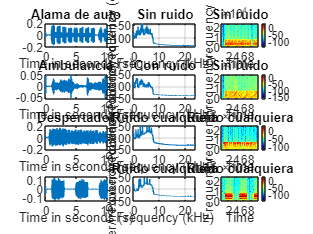

play(recObj);
x_record = getaudiodata(recObj);
n9 = 0:length(x_record)-1;
figure
plot(n9/fs_r,x_record);
title('Audio Signal (double)');

% tono de llamada 7p
[x,fs]=audioread('alarma de auto.wav');
n=0:length(x)-1;
% tono de llamada 7p con ruido
[x1,fs1]=audioread('ambulancia.wav');
n1=0:length(x1)-1;
% audio cualquiera
[x2,fs2]=audioread('despertador.wav');
n2=0:length(x2)-1;
% audio cualquiera
[x3,fs3]=audioread('tono_llamad.wav');
n3=0:length(x3)-1;




% Initial values for the sample lenght
% Spectral analysis sin ruido
L = 0.1*fs;
D = 0.5*L;
nfft = 2^nextpow2(L);
% Spectral analysis con ruido
L1 = 0.1*fs1;
D1=0.5*L1;
nfft1 =  2^nextpow2(L1);
% Spectral analysis señal cualquiera
L2 = 0.1*fs2;
D2= 0.05*L2;
nfft2 =  2^nextpow2(L2);
% Spectral analysis señal cualquiera
L3 = 0.1*fs3;
D3= 0.5*L3;
nfft3 =  2^nextpow2(L3);

figure()
subplot(4,3,1)
plot(n/fs,x) % respecto al tiempo
xlabel("Time in seconds (s)")
title("Alama de auto")
subplot(4,3,2)
pwelch(x, hamming(L),D,nfft,fs)
title("Sin ruido")
subplot(4,3,3)
specgram(x,nfft,fs,hamming(L),D)
colorbar()
title("Sin ruido")
subplot(4,3,4)
plot(n1/fs1,x1) % respecto al tiempo
xlabel("Time in seconds (s)")
title("Ambulancia")
subplot(4,3,5)
pwelch(x1, hamming(L1),D1,nfft1,fs1)
title("Con ruido")
subplot(4,3,6)
specgram(x1,nfft1,fs1,hamming(L1),D1)
colorbar()
title("Sin ruido")
subplot(4,3,7)
plot(n2/fs2,x2) % respecto al tiempo
xlabel("Time in seconds (s)")
title("Despertador")
subplot(4,3,8)
pwelch(x2, hamming(L2),D2,nfft2,fs2)
title("Ruido cualquiera")
subplot(4,3,9)
specgram(x2,nfft2,fs2,hamming(L2),D2)
colorbar()
title("Ruido cualquiera")
subplot(4,3,10)
plot(n3/fs3,x3) % respecto al tiempo
xlabel("Time in seconds (s)")
subplot(4,3,11)
pwelch(x3, hamming(L3),D3,nfft3,fs3)
title("Ruido cualquiera")
subplot(4,3,12)
specgram(x3,nfft3,fs3,hamming(L3),D3)
colorbar()
title("Ruido cualquiera")




%MFCC bases de datos
coeffs = mfcc(x,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L)); % diagrama de MFCC
coeffs1 = mfcc(x1,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L)); % diagrama de MFCC
coeffs2 = mfcc(x2,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L)); % diagrama de MFCC 
coeffs3 = mfcc(x3,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L)); % diagrama de MFCC 


%MFCC señal input
coeffs4 = mfcc(x_record,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L)); % diagrama de MFCC

%plots mfcc
figure
subplot(2,2,1)
mfcc(x,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L),"LogEnergy","Ignore"); % diagrama de MFCC
title("Sin ruido")
subplot(2,2,2)
mfcc(x1,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L),"LogEnergy","Ignore");
title("Con ruido")
subplot(2,2,3)
mfcc(x2,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L),"LogEnergy","Ignore");
title(" Ruido cualquiera")
subplot(2,2,4)
mfcc(x3,fs,"FFTLength",nfft,"OverlapLength",D,"Window",hamming(L),"LogEnergy","Ignore");
title(" Ruido cualquiera")

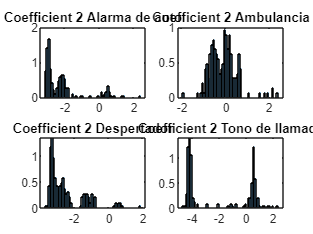


%Resta de matriz de coeficientes hasta el 50vo orden
matriz =  coeffs4 - coeffs;
matriz1 = coeffs4 - coeffs1;
matriz2 = coeffs4 - coeffs2;
matriz3 = coeffs4 - coeffs3;


nbins = 60;
coefficientToAnalyze = 2;
figure
subplot(2,2,1)
histogram(coeffs(:,coefficientToAnalyze+1),nbins,"Normalization","pdf")
title(sprintf("Coefficient %d Alarma de auto",coefficientToAnalyze))
subplot(2,2,2)
histogram(coeffs1(:,coefficientToAnalyze+1),nbins,"Normalization","pdf")
title(sprintf("Coefficient %d Ambulancia",coefficientToAnalyze))
subplot(2,2,3)
histogram(coeffs2(:,coefficientToAnalyze+1),nbins,"Normalization","pdf")
title(sprintf("Coefficient %d Despertador",coefficientToAnalyze))
subplot(2,2,4)
histogram(coeffs3(:,coefficientToAnalyze+1),nbins,"Normalization","pdf")
title(sprintf("Coefficient %d Tono de llamada",coefficientToAnalyze))

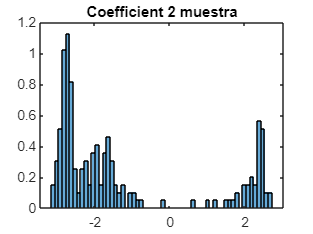


for i=1:size(coeffs,2)
   media(i)= mean(coeffs(:,i));
   sd(i)= std(coeffs(:,i));
   media1(i) = mean(coeffs1(:,i));
   sd1(i)= std(coeffs1(:,i));
   media2(i) = mean(coeffs2(:,i));
   sd2(i)= std(coeffs2(:,i));
   media3(i) = mean(coeffs3(:,i));
   sd3(i)= std(coeffs3(:,i));
   media4(i) = mean(coeffs4(:,i)); 
   sd4(i) = std(coeffs4(:,i));

   %thresholds
   t_h(i) = media(i)+ 1*sd(i); 
   t_l(i) = media(i)- 1*sd(i);

   t_h1(i) = media1(i)+ 1*sd1(i); 
   t_l1(i) = media1(i)- 1*sd1(i);

   t_h2(i) = media2(i)+ 1*sd2(i); 
   t_l2(i) = media2(i)- 1*sd2(i);

   t_h3(i) = media3(i)+ 1*sd3(i); 
   t_l3(i) = media3(i)- 1*sd3(i);
end

for i=1:size(coeffs,2)
   if (media4(i)<t_h(i) && media4(i)>t_l(i))
       checa(i) = 1;
   else
       checa(i) = 0;
   end

   if (media4(i)<t_h1(i) && media4(i)>t_l1(i))
       checa1(i) = 1;
   else
       checa1(i) = 0;
   end

   if (media4(i)<t_h2(i) && media4(i)>t_l2(i))
       checa2(i) = 1;
   else
       checa2(i) = 0;
   end

   if (media4(i)<t_h3(i) && media4(i)>t_l3(i))
       checa3(i) = 1;
   else
       checa3(i) = 0;
   end
end

% Comparación

sum_checa= sum(checa(:));
sum_checa1= sum(checa1(:));
sum_checa2= sum(checa2(:));
sum_checa3= sum(checa3(:));

figure
histogram(coeffs4(:,coefficientToAnalyze+1),nbins,"Normalization","pdf")
title(sprintf("Coefficient %d muestra",coefficientToAnalyze))



if sum_checa>sum_checa1 && sum_checa>sum_checa2 && sum_checa>sum_checa3
    disp("Alarma de auto")
elseif sum_checa1>sum_checa && sum_checa1>sum_checa2 && sum_checa1>sum_checa3
    disp("Ambulancia")
elseif sum_checa2>sum_checa && sum_checa2>sum_checa1 && sum_checa2>sum_checa3
    disp("Despertador")
elseif sum_checa3>sum_checa && sum_checa3>sum_checa1 && sum_checa3>sum_checa2
    disp("Tono de llamada")
else
    disp("Nel")
end

Tono de llamada
